# Atividade 10_03

Otávio Baziewicz Filho - 1942808

clc; clear; close all; 

## Rotulação e propriedades de componentes conexos em imagens binárias  

Faça um script para deixar apenas as 30% maiores células na imagem whitecells4.png e eliminar (apagar, transformando em fundo) todas as outras.

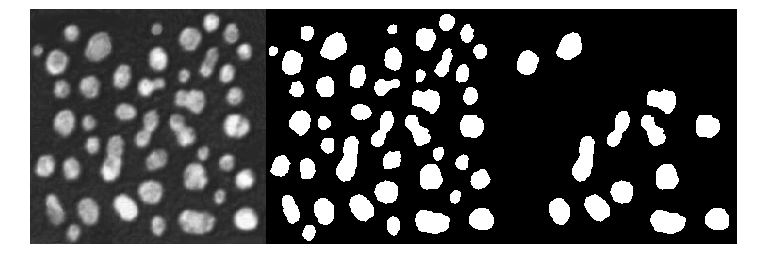

img = imread("whitecells4.png");

th = graythresh(img);
bw = imbinarize(img, th);

[rv, nlabels] = bwlabel(bw, 8);

area = zeros(1, nlabels);
linearIdx = cell(1, nlabels);

for k = 1:nlabels
    linearIdx{k} = find(rv == k);
    area(k) = length(linearIdx{k});
end


bw2 = bw;
maxValueToRemove = mink(area, ceil(0.7 * nlabels));
area(area < maxValueToRemove(end)) = 0;
area(area >= maxValueToRemove(end)) = 1;

for i = 1:nlabels
    if area(i) == 0
        bw2(linearIdx{i}) = 0;
    end
end

figure, montage({img, bw, bw2}, "Size", [1 3])